# Notebook 03: ANN Training

This research project contains 3 notebooks:

- Notebook 01: Project Overview

- Notebook 02: Preprocessing and Feature Extraction

- Notebook 03: ANN Training

You are currently running **Notebook 03**. Before running this notebook, you should have run Notebook 02 to generate features from the neural data.

## Step 1: Load the neural features

Before proceeding, ensure you've run the last cell of the Feature Extraction section in `notebook 02`, which saves your neural features to the `results` folder in your workspace.

clearvars
load("datasets\training_dataset.mat")
load("results\features.mat")

## Step 2: Determine the dimensions of the mapping

For this section, you have been provided with a Multilayer Feedforward Network. You are welcome to use your own architecture, but the explanations in this notebook are only apply to the provided network.

Remember that a neural network can be thought of as a [universal function approximator.](https://www.cs.cmu.edu/~epxing/Class/10715/reading/Kornick_et_al.pdf) This means that your network learns a one-to-one mapping between your input vectors and your output vectors:


$$\vec{x_{out}} = f(\vec{x_{in}})$$


For this reason, you must ensure that the network has the same number of input vectors as output vectors during training.

Your output vectors are the hand's kinematics, which are a set of `N` vectors with dimensionality `1x2.`

Your input vectors are a set of `N` vectors with dimensionality `1xM`, where `M` is determined by your feature extraction methods.

`N,` in this case, corresponds to the number of samples in the `hand_kinematics` of the training set.

First, verify that your have the same number of samples for the features and the kinematics, which will act as our feature labels (i.e., the values we are trying to predict).  

feature_labels = training_data.hand_kinematics;
features = neural_features;
assert(length(features) == length(feature_labels));

How many outputs do we want? Well, that depends on the number of degrees of freedom we are predicting, which in our case is:

n_outputs = width(feature_labels)

n_outputs = 2

How many features per sample do you have in total? That depends on the choices you made in `notebook_02`, including but not limited to:

- How many channels (out of the six provided in the dataset) you decided to use

- How many features per channel you calculated

n_features = width(features);

How many timestamps are there?

n_timestamps = length(feature_labels);

After providing this information, we know that **for every timestamp** in features:

fprintf('Your neural network will map a %dx1 vector to a %dx1 vector', n_features, n_outputs)

Your neural network will map a 2x1 vector to a 2x1 vector

## Step 3: Implement and train the neural network

### A) Reshape input features

Due to MATLAB's limited selection of [input layers](https://www.mathworks.com/help/deeplearning/ug/list-of-deep-learning-layers.html), we will be using the [`imageInputLayer`](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.imageinputlayer.html) option.

This requires that we reshape our features by adding additional "dummy" dimensions to satisfy the `imageInputLayer` API.

image_input_size = [n_features, 1, 1];
reshaped_features = zeros([image_input_size, n_timestamps]);
for timestamp = 1:n_timestamps
    reshaped_features(:,:,:, timestamp) = features(timestamp,:)';
end

### B) Declare the architecture layers

The following is a feedforward neural network, which is the simplest form of neural network. It is made of fully connected layers of perceptrons. 

% Feel free to change the architecture
network_layers = [ ...
    imageInputLayer(image_input_size)
    fullyConnectedLayer(n_features*2)
    tanhLayer
    fullyConnectedLayer(n_features*3)
    tanhLayer
    fullyConnectedLayer(n_features*3)
    tanhLayer
    fullyConnectedLayer(n_features*2)
    tanhLayer
    fullyConnectedLayer(n_outputs)
    regressionLayer
    ]

network_layers =   11×1 Layer array with layers:

     1   ''   Image Input         2×1×1 images with 'zerocenter' normalization
     2   ''   Fully Connected     4 fully connected layer
     3   ''   Tanh                Hyperbolic tangent
     4   ''   Fully Connected     6 fully connected layer
     5   ''   Tanh                Hyperbolic tangent
     6   ''   Fully Connected     6 fully connected layer
     7   ''   Tanh                Hyperbolic tangent
     8   ''   Fully Connected     4 fully connected layer
     9   ''   Tanh                Hyperbolic tangent
    10   ''   Fully Connected     2 fully connected layer
    11   ''   Regression Output   mean-squared-error

### C) Train the neural network

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         0.49 |          0.1 |          0.1000 |
|       1 |          50 |       00:00:03 |         0.28 |      4.1e-02 |          0.1000 |
|       1 |         100 |       00:00:04 |         0.34 |      5.8e-02 |          0.1000 |
|       1 |         150 |       00:00:04 |         0.31 |      4.9e-02 |          0.1000 |
|       1 |         200 |       00:00:05 |         0.32 |      5.0e-02 |          0.1000 |
|       1 |         250 |       00:00:06 |         0.29 |      4.1e-02 |          0.1000 |
|       1 |         300 |  

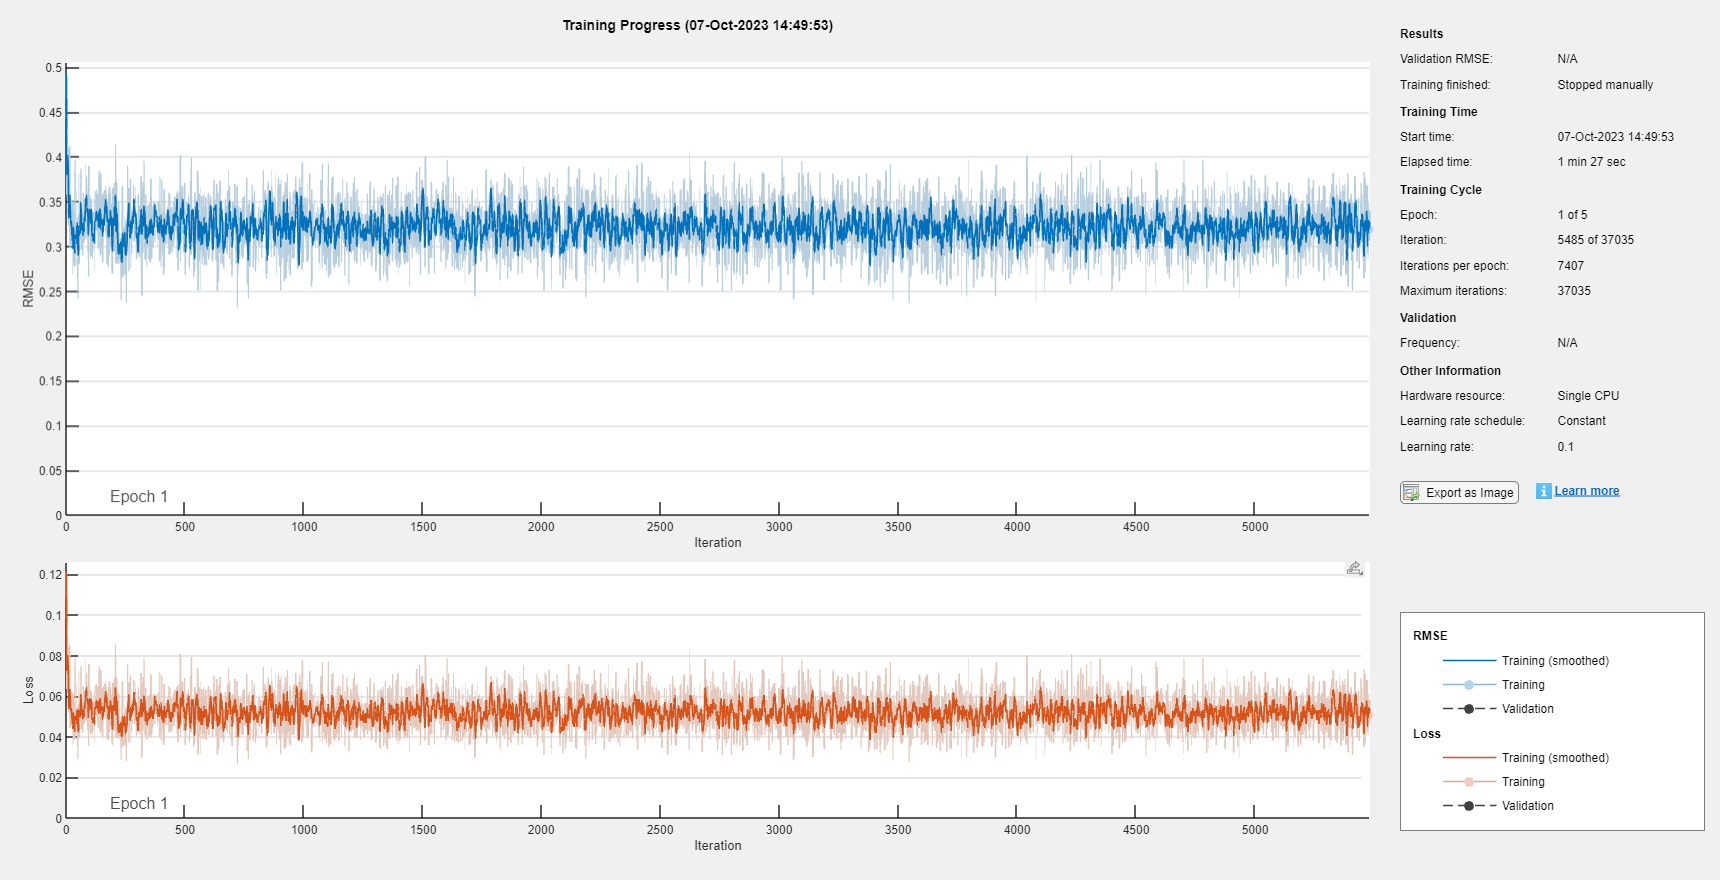

neural_net =   SeriesNetwork with properties:

         Layers: [11×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'regressionoutput'}


% Feel free to experiment with the training options
training_options = trainingOptions( "sgdm", ...
                                    InitialLearnRate=0.1, ...
                                    MaxEpochs=5, ...
                                    Shuffle="every-epoch", ...
                                    Plots="training-progress");
neural_net = trainNetwork(reshaped_features, feature_labels, network_layers, training_options)

## Step 4: Test the neural network against unseen data

### A) Load the testing dataset

load("datasets\testing_dataset.mat")

You need to apply the same preprocessing steps as you did for your training data

### B) Filter the data

Refer to **Step 3** of the **Preprocessing** section in **Notebook 2**.

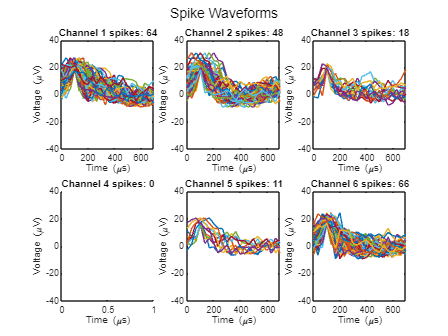

%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% filt_neural_data = testing_data.raw_neural_data;
sample_rate = 30000; % Change this random value to the actual value of the sample rate
cut_off_freq = 30; % Change this random value
% Wavelet denoising
wname = 'db4'; % Wavelet type (you can change this if needed)
level = 5; % Decomposition level (adjust as needed)
num_channels = 6;

filt_order = 4;
norm_cut_off = cut_off_freq / (sample_rate/2);
[b, a] = butter(filt_order, norm_cut_off, 'high'); % 4th order highpass filter
ch_init_conds = zeros(filt_order, 6); %initial conditions for filter for all channels
temporal_raw = testing_data.raw_neural_data;
rectified_data = abs(temporal_raw);
[filt_neural_data, ~] = FilterX(b, a, rectified_data, ch_init_conds);
[filt_neural_data2, ~] = FilterX(b, a, temporal_raw, ch_init_conds);
% get signal avg
neural_data_rms = rms(filt_neural_data);
% get signal standard deviation
neural_data_sd = std(filt_neural_data);
% Perform wavelet decomposition
denoised_data = zeros(size(rectified_data));
envelope_data = zeros(size(rectified_data));
for channel = 1:num_channels
    % Compute the envelope of the original signal
    env = abs(hilbert(filt_neural_data2(:, channel)));
    % Perform wavelet decomposition
    % [c, l] = wavedec(filt_neural_data2(:, channel), level, wname);
    [c, l] = wavedec(env, level, wname);

    % Specify a threshold based on a percentage of the maximum coefficients
    threshold_percentage = 10; % Adjust this value as needed
    threshold_value = threshold_percentage / 100 * max(abs(c));

    % Apply thresholding to coefficients
    cnew = wthresh(c, 'h', threshold_value);

    % Reconstruct the denoised signal
    denoised_signal = waverec(cnew, l, wname);

    % Compute the envelope of the denoised signal
    envelope = abs(denoised_signal);

    % Store denoised signal and envelope in matrices
    denoised_data(:, channel) = denoised_signal;
    envelope_data(:, channel) = envelope;
end

% Smooth the envelope using a moving average filter (adjust the window size as needed)
window_size = 1000; % Adjust this to control the smoothing level
smoothed_env_denoised = zeros(size(rectified_data));
for channel = 1:num_channels
    % Smooth the envelope using a moving average filter
    smoothed_env = movmean(envelope_data(:, channel), window_size);
    
    % Store smoothed envelope in the matrix
    smoothed_env_denoised(:, channel) = smoothed_env;
end

smoth_envelop_data_sd = std(smoothed_env_denoised);
denoised_data_sd = std(denoised_data);

% Plot denoised signals and smoothed envelopes for each channel
[num_samples, num_chans] = size(rectified_data);
timestamps = (1:num_samples)/sample_rate;
figure;

% for channel = 1:num_channels
%     subplot(num_channels, 2, 2 * channel - 1);
%     plot(timestamps, denoised_data(:, channel));
%     xlabel('Time (s)');
%     ylabel('Amplitude');
%     title(['Denoised EMG Signal - Channel ', num2str(channel)]);
% 
%     subplot(num_channels, 2, 2 * channel);
%     plot(timestamps, smoothed_env_denoised(:, channel));
%     xlabel('Time (s)');
%     ylabel('Amplitude');
%     title(['Smoothed Envelope - Channel ', num2str(channel)]);
% end
% SPIKE LOCATION
spike_locations_b3 = zeros(size(filt_neural_data));
spike_locations_denoised_b3 = zeros(size(filt_neural_data2));
spike_locations_smooth_b3 = zeros(size(filt_neural_data2));
spike_locations_combined_b3 = zeros(size(filt_neural_data2));
for idx1 = 1:6
    % Initialize the sub_spike_array
    sub_data_array = filt_neural_data(:, idx1);
    % Initialize the sub_spike_array
    sub_spike_array = zeros(size(sub_data_array));
    
    for idx2 = 1:length(sub_spike_array)
        if sub_data_array(idx2) > (5.5 * neural_data_sd(idx1))
            % Update the corresponding value in sub_spike_array
            sub_spike_array(idx2) = 1;
        end
    end
    % Assign the updated sub_spike_array to spike_locations
    spike_locations_b3(:, idx1) = sub_spike_array;
end
for idx1 = 1:6
    % Initialize the sub_spike_array
    sub_data_array = smoothed_env_denoised(:, idx1);
    % Initialize the sub_spike_array
    sub_spike_array = zeros(size(sub_data_array));

    for idx2 = 1:length(sub_spike_array)
        if sub_data_array(idx2) > (13.5* smoth_envelop_data_sd(idx1))
            % Update the corresponding value in sub_spike_array
            if sub_spike_array(idx2) ~= 1
                if idx1 == 6
                    sub_spike_array(idx2) = 0;
                else
                    sub_spike_array(idx2) = 1;
                end
            end
        end
    end
    % Assign the updated sub_spike_array to spike_locations
    spike_locations_smooth_b3(:, idx1) = sub_spike_array;
end
for idx1 = 1:6
    % Initialize the sub_spike_array
    sub_data_array = denoised_data(:, idx1);
    % Initialize the sub_spike_array
    sub_spike_array = zeros(size(sub_data_array));

    for idx2 = 1:length(sub_spike_array)
        if sub_data_array(idx2) > (13.5 * denoised_data_sd(idx1)) 
            % Update the corresponding value in sub_spike_array
            if sub_spike_array(idx2) ~= 1
                if idx1 == 6
                    sub_spike_array(idx2) = 0;
                else
                    sub_spike_array(idx2) = 1;
                end
            end
        end
    end
    % Assign the updated sub_spike_array to spike_locations
    spike_locations_denoised_b3(:, idx1) = sub_spike_array;
end
for idx1 = 1:6
    % Initialize the sub_spike_array
    sub_data_array1 = denoised_data(:, idx1);
    sub_data_array2 = smoothed_env_denoised(:, idx1);
    % Initialize the sub_spike_array
    sub_spike_array = zeros(size(sub_data_array1));

    for idx2 = 1:length(sub_spike_array)
        if sub_data_array1(idx2) > (13 * denoised_data_sd(idx1)) 
            % Update the corresponding value in sub_spike_array
            if sub_spike_array(idx2) ~= 1
                if idx1 == 6
                    sub_spike_array(idx2) = 0;
                else
                    sub_spike_array(idx2) = 1;
                end
            end
        end
        if sub_data_array2(idx2) > (13* smoth_envelop_data_sd(idx1))
            % Update the corresponding value in sub_spike_array
            if sub_spike_array(idx2) ~= 1
                if idx1 == 6
                    sub_spike_array(idx2) = 0;
                else
                    sub_spike_array(idx2) = 1;
                end
            end
        end
    end
    % Assign the updated sub_spike_array to spike_locations
    spike_locations_combined_b3(:, idx1) = sub_spike_array;
end

% PLOT SPIKE LOCATIONS
% fig_3 = plot_spike_trains(spike_locations_b3, testing_data);
% fig_4 = plot_spike_trains(spike_locations_denoised_b3, testing_data);
% fig_5 = plot_spike_trains(spike_locations_smooth_b3, testing_data);
% fig_6 = plot_spike_trains(spike_locations_combined_b3, testing_data);

% GET & PLOT SPIKES WAVEFORMS
spike_waveforms = get_action_potentials(spike_locations_b3, filt_neural_data, 'Spike Waveforms');


% GET SPIKES SNRs
snr_waveforms = cell(6, 1);
for chan_idx = 1:6 % for each channel
    chan_waveforms = spike_waveforms{chan_idx};
    snr_array = cell(1, length(chan_waveforms));
    for waveform_idx = 1:length(chan_waveforms) % for each waveform in the channel
        waveform_data = chan_waveforms{waveform_idx};
        %%%%%%%%%%%%%%%%%%%%%%%% YOUR SNR CODE GOES HERE %%%%%%%%%%%%%%%%%%%
        % snr_array = cell(1, length(chan_waveforms));
        % Extract the baseline noise 
        noise_baseline = neural_data_sd(chan_idx);
        % Calculate the amplitude of the spike (peak-to-peak)
        spike_amplitude = max(waveform_data) - min(waveform_data);
        % Calculate the SNR for the spike
        snr = 10*log10((spike_amplitude.^2)/(noise_baseline.^2));
        % snr_waveforms(waveform_idx, chan_idx) = snr;
        snr_array{waveform_idx} = snr;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    end
    snr_waveforms{chan_idx} = snr_array;
end
% Create or open a CSV file to write the SNR values
csv_filename = 'snr_values_b3.csv';
csv_fid = fopen(csv_filename, 'w');

% Write the header row with channel names
for chan_idx = 1:6
    fprintf(csv_fid, 'Channel %d', chan_idx);
    if chan_idx < 6
        fprintf(csv_fid, ',');
    else
        fprintf(csv_fid, '\n');
    end
end

% Write the SNR values to the CSV file by column
for waveform_idx = 1:max(cellfun(@length, snr_waveforms)) % Iterate through waveforms
    for chan_idx = 1:6 % Iterate through channels
        if waveform_idx <= length(snr_waveforms{chan_idx})
            snr_value = snr_waveforms{chan_idx}{waveform_idx};
            fprintf(csv_fid, '%f', snr_value);
        end
        if chan_idx < 6
            fprintf(csv_fid, ',');
        else
            fprintf(csv_fid, '\n');
        end
    end
end

% Close the CSV file
fclose(csv_fid);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### C) Generate neural features from the testing dataset

Refer to the **Feature Extraction** section in **Notebook 2.**

%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

kernel_size = 10000; % Adjust the kernel size as needed
smoothing_kernel = ones(1, kernel_size) / kernel_size;
% Specify the indices you want to extract
selected_features = [1, 2];
% Normalize the kernel
smoothing_kernel = smoothing_kernel / max(smoothing_kernel);

combined_spikes_feature1 = spike_locations_b3(:, 1);
combined_spikes_feature1 = zeros(size(combined_spikes_feature1));
combined_spikes_feature2 = spike_locations_denoised_b3(:, 1);

selected_Ch_feature1 = [1, 2];
selected_Ch_feature2 = [1, 2];
% Loop through the selected subarrays and update the combined_spikes_array
for idx = selected_Ch_feature1
    combined_spikes_feature1 = combined_spikes_feature1 | spike_locations_b3(:, idx);
end
% % Loop through the selected subarrays and update the combined_spikes_array
for idx = selected_Ch_feature2
    combined_spikes_feature2 = combined_spikes_feature2 | spike_locations_smooth_b3(:, idx);
end

feature1_b3 = combined_spikes_feature1;
feature1_b3 = conv(feature1_b3, smoothing_kernel, 'same');
feature1_b3 = normalize(feature1_b3, "range", [0 30]);

feature2_b3 = combined_spikes_feature2;
feature2_b3 = conv(feature2_b3, smoothing_kernel, 'same');
feature2_b3 = normalize(feature2_b3, "range", [0 30]);

neural_features_b3 = spike_locations_combined_b3(:, selected_features);
neural_features_b3 = zeros(size(neural_features_b3));
neural_features_b3(:, 1) = feature1_b3;
neural_features_b3(:, 2) = feature2_b3;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
assert(length(neural_features_b3) == length(testing_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")

### D) Reshape the neural features

Refer to **Step 3** of **Notebook 3**

feature_labels = testing_data.hand_kinematics;
features = neural_features_b3;
assert(length(features) == length(feature_labels));
n_outputs = width(feature_labels)

n_outputs = 2

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         0.57 |          0.2 |          0.1000 |
|       1 |          50 |       00:00:02 |         0.24 |      2.8e-02 |          0.1000 |
|       1 |         100 |       00:00:04 |         0.25 |      3.1e-02 |          0.1000 |
|       1 |         150 |       00:00:04 |         0.28 |      3.9e-02 |          0.1000 |
|       1 |         200 |       00:00:05 |         0.21 |      2.2e-02 |          0.1000 |
|       1 |         250 |       00:00:06 |         0.25 |      3.2e-02 |          0.1000 |
|       1 |         300 |  

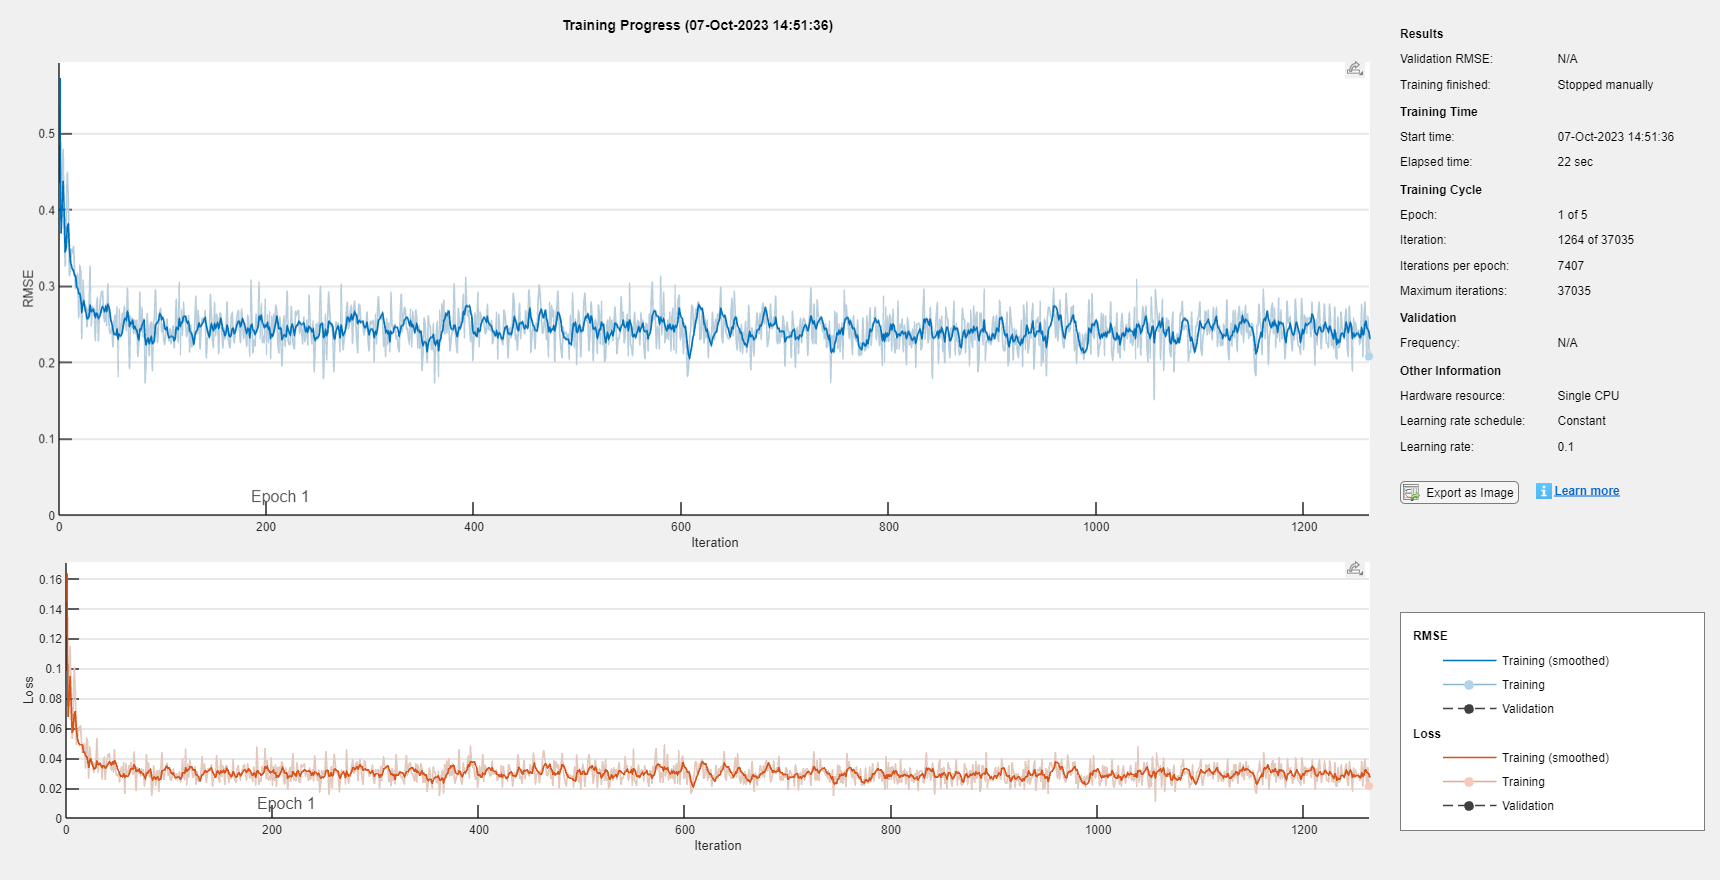

neural_net =   SeriesNetwork with properties:

         Layers: [11×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'regressionoutput'}


n_features = width(neural_features_b3);
n_timestamps = length(testing_data.hand_kinematics);
image_input_size = [n_features, 1, 1];
% fprintf('Your neural network will map a %dx1 vector to a %dx1 vector', n_features, n_outputs)

reshaped_features = zeros([image_input_size, n_timestamps]);
for timestamp = 1:n_timestamps
    reshaped_features(:,:,:, timestamp) = neural_features_b3(timestamp,:)';
end

% ----
% Feel free to change the architecture
network_layers = [ ...
    imageInputLayer(image_input_size)
    fullyConnectedLayer(n_features*2)
    tanhLayer
    fullyConnectedLayer(n_features*3)
    tanhLayer
    fullyConnectedLayer(n_features*3)
    tanhLayer
    fullyConnectedLayer(n_features*2)
    tanhLayer
    fullyConnectedLayer(n_outputs)
    regressionLayer
    ];
% -----
% Feel free to experiment with the training options
training_options = trainingOptions( "sgdm", ...
                                    InitialLearnRate=0.1, ...
                                    MaxEpochs=5, ...
                                    Shuffle="every-epoch", ...
                                    Plots="training-progress");
neural_net = trainNetwork(reshaped_features, feature_labels, network_layers, training_options)

### E) Predict the testing kinematics based on your generated features

kinematics_predicted = predict(neural_net, reshaped_features);
kinematics_observed = testing_data.hand_kinematics;

### D) Compare your predictions with the actual values of the kinematics

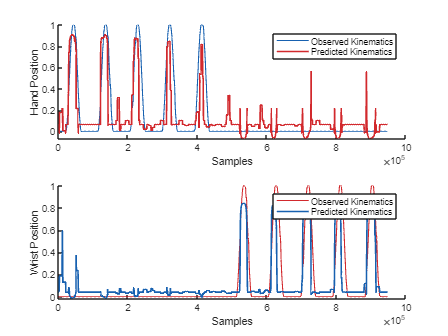

figure
tlo = tiledlayout('flow');
nexttile
hold on
plot(kinematics_observed(:,1), 'LineStyle','-','Color', "#1761B0", 'LineWidth', 1)
plot(kinematics_predicted(:,1), 'LineStyle','-','Color', "#D2292D", 'LineWidth', 1.5)
hold off
xlabel("Samples")
ylabel("Hand Position")
legend(["Observed Kinematics", "Predicted Kinematics"])

nexttile
hold on
plot(kinematics_observed(:,2), 'LineStyle','-','Color', "#D2292D", 'LineWidth', 1)
plot(kinematics_predicted(:,2), 'LineStyle','-','Color', "#1761B0", 'LineWidth', 1.5)
hold off
legend(["Observed Kinematics", "Predicted Kinematics"])
xlabel("Samples")
ylabel("Wrist Position")
legend(["Observed Kinematics", "Predicted Kinematics"])

## Helper Functions

This section contains the functions used for data visualization throughout this notebook. You do not need to change or understand the code below, but you are welcome to do so if it helps with your project.

function fig_handle = plot_raw_data(training_data)
[num_samples, num_chans] = size(training_data.raw_neural_data);
timestamps = (1:num_samples)/training_data.sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    ax_handles{i} = nexttile;
    plot(timestamps, training_data.raw_neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [\muV]')
end
title(fig_raw, 'Raw Neural Data')
linkaxes([ax_handles{:}], 'xy');
ylim([-50, 50])
end


function fig_handle = plot_filt_data(neural_data, sample_rate)
[num_samples, num_chans] = size(neural_data);
timestamps = (1:num_samples)/sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    ax_handles{i} = nexttile;
    plot(timestamps, neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [\muV]')
end
title(fig_raw, 'Filtered Neural Data')
linkaxes([ax_handles{:}], 'xy');
ylim([-50, 50])
end


function fig_handle = plot_spike_trains(spike_locations, training_data)
fig_handle = figure;
t = (0:1:length(spike_locations)-1)'/training_data.sample_rate;
raster_handle = stackedplot(t, [training_data.hand_kinematics, spike_locations], LineWidth=1.5);
raster_handle.DisplayLabels = ["Hand Kinematics 1", "Hand Kinematics 2", "CH 01", "CH 02", "CH 03", "CH 04", "CH 05", "CH 06"];
raster_handle.XLabel = "Time [sec]";
raster_handle.Title = "Raster Plot";
end


function spike_waveform_container = get_action_potentials(spike_trains, neural_data, plot_title)
[~, n_chans] = size(neural_data);
figure()
sgtitle(plot_title)
spike_waveform_container = cell(n_chans,1);
for chan=1:n_chans
    neg_offset = -3;
    pos_offset = 18;
    spike_locations = spike_trains(:,chan);
    spike_locations = find(spike_locations == 1);
    spike_count = sum(spike_trains);
    spikes = cell(1, spike_count(chan));

    subplot(2, 3, chan)
    for spike_idx = 1:length(spikes)
        idx_start = spike_locations(spike_idx) + neg_offset;
        idx_end = spike_locations(spike_idx) + pos_offset;
        try
            spikes{spike_idx} = neural_data(idx_start:idx_end, chan);
            plot(0:33:700, spikes{spike_idx});
        catch
        end
        hold on;
        spike_waveform_container{chan} = spikes;
    end
    xlabel('Time (\mus)')
    ylabel('Voltage (\muV)')
    hold off
    title(['Channel ' num2str(chan) ' spikes: ' num2str(length(spikes))])
    ylim([-40, 40])
end
end
